# Network Opinion Manipulation

## Dataset

We are dealing with a direct graph since A is not symetrical.

clear
close all
load("PiecewiseSparse.mat") 
% we are dealing with direct graph problem 

## Model

Dynamic model:


$$X_n ={\bar{A} }^n \cdot X_0 +{\bar{A} }^{n-1} \cdot U_0 +\ldotp \ldotp \ldotp +{\bar{A} }^1 \cdot U_{n-2} +U_{n-1}$$



$$\phi_N =\left\lbrack \begin{array}{ccccc}
{\bar{A} }^{n-1}  & {\bar{A} }^{n-2}  & \cdots  & {\bar{A} }^1  & I_{25} 
\end{array}\right\rbrack$$



$$U_N =\left\lbrack \begin{array}{c}
U_0 \\
U_1 \\
\cdots \;\\
U_{n-1} 
\end{array}\right\rbrack$$



$$X_n ={\bar{A} }^n \cdot X_0 +\phi_N \cdot U_N$$



$$X_n -{\bar{A} }^n \cdot X_0 =\phi_N \cdot U_N$$


formulate a recovery problem with Um a vector with N blocks, each block is s-sparsity

Measurement model Am:


$$\begin{array}{l}
A_{m\;} =\phi {\;}_N \odot M\cdot \left(U\odot U\right)\\
U=\textrm{dctmtx}\left(25\right)\;\\
M:\textrm{each}\;\textrm{row}\;\textrm{is}\;\textrm{sampled}\;\textrm{at}\;\textrm{given}\;\textrm{ratio},\textrm{all}\;\textrm{elements}\in \left\lbrace 0,1\right\rbrace ,\textrm{value}\;1\;\textrm{stands}\;\textrm{for}\;\textrm{chose}\;\textrm{signal}\ldotp 
\end{array}$$


% one realization
A = normr(A);
n = 25;
X_f = FinalState(1, :)';
X_0 = zeros(size(X_f));
phi = zeros(n, n*n);
for i = 1:n
    phi(:, (i-1)*n+1:i*n) = A^(n-i);
end
y = X_f - A^n * X_0;
% s = 5; % sparsity 20%
% Am = zeros(n, n*n);
% ratio = 0.2;
Am = phi

Am =    -3.1598    1.0029    3.8167   -3.9582    2.4076    2.3067    0.3241   -2.9851    3.6139   -0.2859    4.0699   -5.5093   -2.2553   -0.7965    3.9578    2.9037    2.8262   -0.1326   -2.7969    1.3185   -1.8833   -0.5586    1.7497   -2.5892    3.8586   -0.1970    0.1237   -3.2659    2.6157   -1.9235   -2.2295    0.2654    2.3191   -2.1407   -0.3343   -2.5952    4.1854    0.6242    2.3442   -3.8078   -2.0249   -1.1697    0.6916    3.3515    1.7987    3.6943    3.3023   -1.7537    1.2125   -2.9944
    4.5777   -3.4651    1.5453   -3.3686    0.4396    2.1091    1.0589   -0.0319    0.0382    0.0117   -2.7892   -4.1585    2.3386   -1.2318   -1.7929    1.0748   -5.2720    3.4885   -1.8898   -5.7766   -5.7252   -7.0712   -2.7913   -1.0142   -1.4877   -5.1894    1.8474   -0.5817    1.3282    1.7352   -0.4757   -1.2703   -1.0295    0.4335   -0.8527    3.8242    2.7974   -2.5286   -0.0149    2.0301   -0.0579    5.6829   -1.4197    0.1346    4.9629    4.3955    5.7874    3.6878    0.0794    


% U = dctmtx(n);
% psi = kron(U, U);
% 
% for i = 1:n
%     samp_idx = zeros(n*s,1);
%     % sampling
%     for j = 1:n
%         samp_idx((j-1)*s+1:j*s) = randperm(n, s) + (j-1)*25*ones(1,s);
%     end
%     
%     Am(i, samp_idx) = phi(i, samp_idx);
%     % Am(i,:) = Am(i,:) * psi;
% end

## Controllability


$$Rank{[\bar{A} \ I_S]} = Rank{[\bar{A}_{S,:} \ I; \bar{A}_{S^c,:} \ I]}$$


if the $\bar{A}_{S^c} $ is full row rank, then the system is controllable. 

n = 25;
s = 5;
for s = 1:25
    sample_idx = randperm(n, s);
    rest_idx = setdiff(1:n, sample_idx);
    if rank(A(rest_idx, :)) == n-s
        % 
        % sprintf("when {s = %d}, the system is controllable", s)
    end
end

## P-OMP

% input
% D:matrix
% b:measurement
% K:sparsity bound
% K_i:piecewise sparsity
L = 25;
D = Am(:, (25-L)*25+1:625);
y_msmt = FinalState(1, :)';
sparsity = 3;
K = sparsity * 25;
K_i = sparsity * ones(25,1);
block_count = zeros(L, 1); % to track the entry in each block

% initialize
spt = zeros(1, L*25);
abdn = zeros(1, L*25);
result = 0;
resd = y_msmt; % residual, x0 = 0
ptr1 = 1; % pointer of support set
ptr2 = 1; % pointer of abondon set
U = 1:L*25; % universal set

vec_s0 = zeros(L*25, 1);
vec_s = vec_s0;
% iteration
for k = 1:100
    avlb = setdiff(U, abdn(1:ptr2));
    D_k = D(:, avlb);
    h_k = D_k' * resd;
    [max_value, max_idx] = max(abs(h_k));
    omega_k = find_in_original(D, D_k(:, max_idx)');
    spt(ptr1) = omega_k;
    ptr1 = ptr1 + 1;
    % block-wise
    block_idx = in_which_block(omega_k, 25);
    block_count(block_idx) = block_count(block_idx) + 1;
    if block_count(block_idx) == K_i(block_idx)
        % abondan the element from the block
        blk_h = 25 * (block_idx - 1) + 1; blk_t = 25 * block_idx;
        blk_abdn = setdiff(U(blk_h:blk_t), spt(1:ptr1-1)); 
        for j = 1:length(blk_abdn)
            abdn(ptr2) = blk_abdn(j);
            ptr2 = ptr2 + 1;
        end
    end
    D_s = D(:, spt(1:ptr1-1));
    vec_s(spt(1:ptr1-1)) = (D_s'*D_s) \ D_s' * y_msmt;
    resd = y_msmt - D * vec_s;
    norm(resd, 2)
    if (norm(resd, 2) < 0.01) || (ptr1-1 >= K)
        break
    end
end

ans = 6.5843

ans = 6.5825

ans = 6.3910

ans = 5.6825

ans = 5.0218

ans = 4.5294

ans = 4.4437

ans = 3.4430

ans = 2.8480

ans = 2.1045

ans = 1.7782

ans = 1.4296

ans = 1.3137

ans = 1.1874

ans = 1.1202

ans = 1.0327

ans = 0.8165

ans = 0.7431

ans = 0.6310

ans = 0.5614

ans = 0.4695

ans = 0.3377

ans = 0.1777

ans = 0.0589

ans = 7.0991e-12

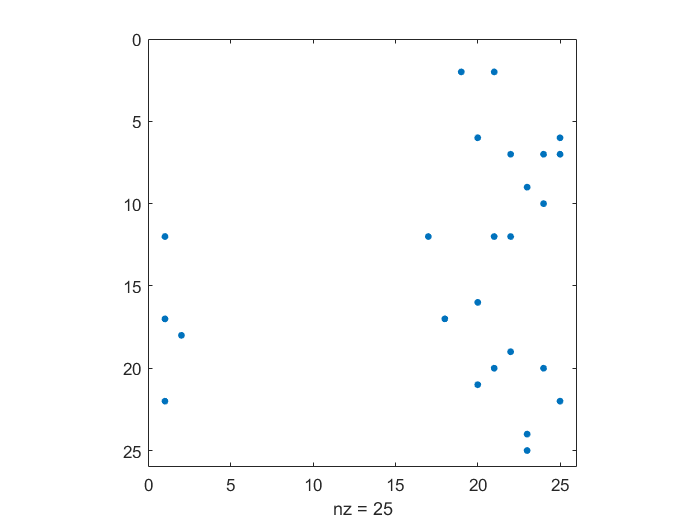

rcsct_x = reshape(vec_s, [25, 25]);
spy(rcsct_x)

## Simulation

Run the simulation over the input and time span, there is some difference between the simulation's final state and the given final state. 

Ad = A; 
Bd = eye(25);
Cd = eye(25);
Dd = 0;

ts = 1;
t = 1:ts:25;
x0 = zeros(25, 1);
u = rcsct_x;
sys = ss(Ad, Bd, Cd, Dd, ts);
[y, t, x] = lsim(sys, u', t, X_0);

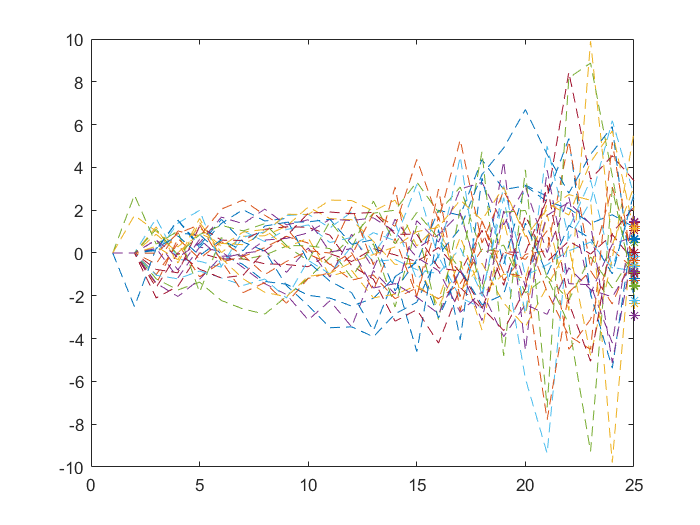

% plot(t, y, "--", 25, y_msmt, "-*");

error_sim = y_msmt - y(25, :)';
error = y_msmt - D * rcsct_x(:);

norm(error_sim, 2)

ans = 11.3857

norm(error, 2)

ans = 7.0991e-12

## Numerical test

## OMP

vec_s = OMP(y_msmt, Am, 25, 0.01)

vec_s =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3115
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.6418
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

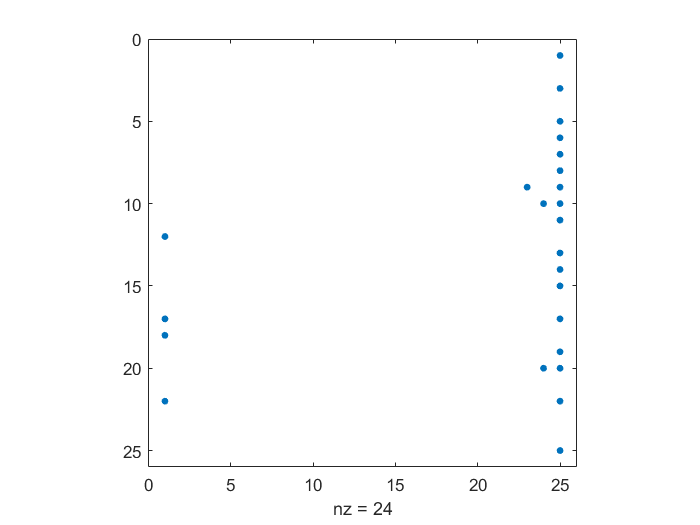

spy(vec_s)

function y = in_which_block(omega, bs)
    y = ceil(omega / bs); 
end
function column=find_in_original(M, v)
    tf = ismember(M', v, "rows");
    column = find(tf);
end

function y = diagonal(A, r)
    y = find(abs(A'*r) == max(abs(A'*r)));
end

function rcsct_x = OMP(y_msmt, A, p_size, e)
    % initialization
    othg_idx = zeros(p_size*p_size, 1);
    ptr = 1;
    vec_z0 = zeros(p_size*p_size, 1);
    vec_z = vec_z0;
    resd = y_msmt;
    for i = 1:1000
        k = diagonal(A, resd);
        if ~ismember(k, othg_idx)
            othg_idx(ptr) = k;
            ptr = ptr + 1;
        end
        A_othg = A(:, othg_idx(1:ptr-1));
        vec_z(othg_idx(1:ptr-1)) = (A_othg'*A_othg) \ A_othg' * y_msmt;
        % inv(A_othg'*A_othg)
        % size(A)
        % size(vec_z)
        resd = y_msmt - A * vec_z;
        if norm(resd) < e
            
            break;
        end
    end
    rcsct_x = reshape(vec_z, [p_size, p_size]);
end


